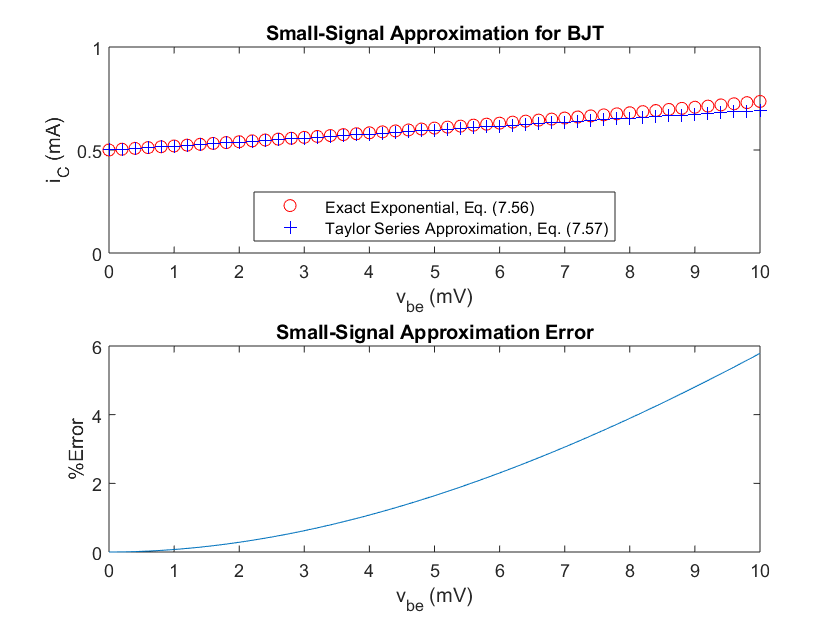

% BJT Small-signal approximation.
%
VT = 0.0259; % This is the thermal voltage at T = 300K (see page 148).
%
% For this example let the dc collector current be IC = 0.5 mA:
IC = 0.5e-3; 
%
vbe = 0:0.2e-3:10e-3; % Applied vbe, 51 points.
%
% The total collector current is given by Eq. (7.56), page 400.
%
iC = zeros(1,51);% Pre-allocate iC for speed, otherwise it's re-sized 
%                   on each iteration of loop below (slow).
for n = 1:51
iC(n) = IC*exp(vbe(n)/VT);% Eq. (7.56), page 400.
end
%
% The small-signal approximation is given by the first two terms of a
% Taylor sereis expansion of Eq. (7.56).
%
iC_approx = zeros(1,51);% Pre-allocate for speed.
for n = 1:51
iC_approx(n) = IC*(1 + vbe(n)/VT); % Eq. (7.57), page 396
end
%
% Next compute the percentage error:
Error = zeros(1,51);% Pre-allocate for speed.
for n = 1:51
    Error(n) = (iC(n) - iC_approx(n))*100/iC(n);
end
%
subplot(2,1,1), plot(vbe*1e3,iC*1e3,'ro',vbe*1e3,iC_approx*1e3,'b+')
title('Small-Signal Approximation for BJT')
xlabel('{v}_{be} (mV)')
ylabel('{i}_{C} (mA)')
axis([0 10 0 1]);
legend('Exact Exponential, Eq. (7.56)','Taylor Series Approximation, Eq. (7.57)','Location','South')
%
subplot(2,1,2), plot(vbe*1e3,Error)
title('Small-Signal Approximation Error')
xlabel('{v}_{be} (mV)')
ylabel('%Error')